# **demo13 of Im2mesh package**

demo13 - 2D mesh for periodic boundary conditions

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Overview

We will demostrate creating a 2D mesh for periodic boundary conditions (PBC). PBC requires node matching on the opposite edges of a Representative Volume Element (RVE).

Node matching for PBC:

- Left and right boundaries: For every node on the left boundary, there must be a corresponding node on the right boundary with the exact same y-coordinate

- Top and bottom boundaries: For every node on the bottom boundary, there must be a corresponding node on the top boundary with the exact same x-coordinate.

In this demo, we will use the following options of function bounds2mesh.

- **opt.tf_preserve** - Boolean. Whether preserve the input edges with minimal refinement. Default value: false. When setting opt.tf_preserve as true, it enables MESH2D to retain the initial edges without further subdivision. Therefore, we can get 2d mesh with node matching.

- **opt.bound_size** - Element size at all boundaries. When opt.bound_size=0, it will disable this parameter. Default value: 0. If opt.bound_size is non-zero, uniform mesh seeds will be added to all boundaries.

- **opt.outerbound_size** - Element size at the outermost boundary. When opt.outerbound_size=0, it will disable this parameter. Default value: 0. If opt.outerbound_size is non-zero, uniform mesh seeds will be added to the outermost boundary.

Note that the actual spacing between the inserted mesh seeds is slightly different from the element size we defined. See equations below.  

            `numSegment = round( len / targetSpace );`

            `actualSpace = len / numSegment;`

where 'len' is the length of an edge. 'targetSpace' is the target spacing between seeds. 'actualSpace' is the actual spacing between seeds.

After we got the generated mesh, we can use function checkPBCNode to check whether the mesh satisfies node matching for PBC.

## Initialize

No need to install any MATLAB toolboxes when running this demo.

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size (optional).

x = 250; y = 250; width = 300; height = 300;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function bounds2mesh use a mesh generator called MESH2D (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Create geometry

### Polyshape

We use Matlab polyshape objects to create a simple RVE for demostration. Suppose we are interested in fiber composites.

Start with a square.

vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create a circle.

t = 0.05:0.1:2*pi;
x1 = 5 + 1.5*cos(t);
y1 = 5 + 1.5*sin(t);
psC0 = polyshape(x1,y1);

Translate

psC1 = translate( psC0, [5.1, 1.5] );
psC2 = translate( psC0, [-4.9, 1.5] );

psC3 = translate( psC0, [1, 5.6] );
psC4 = translate( psC0, [1, -4.4] );

Plot them together: 1 square and 5 circles.

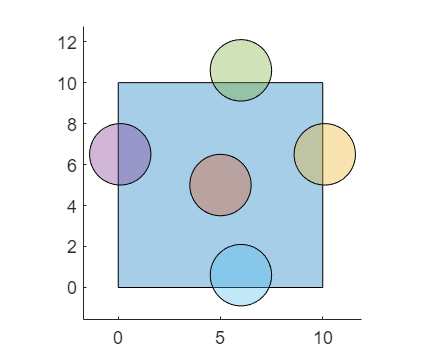

figure
plot( [psSq; psC0; psC1; psC2; psC3; psC4] ); 
axis equal

We saw that they are overlapped.

### Create matrix

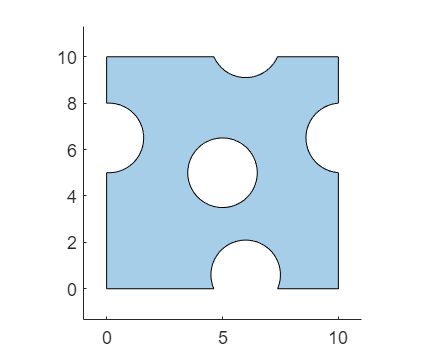

psMatrix = subtract( psSq, psC0 );

psMatrix = subtract( psMatrix, psC1 );
psMatrix = subtract( psMatrix, psC2 );

psMatrix = subtract( psMatrix, psC3 );
psMatrix = subtract( psMatrix, psC4 );

figure
plot( psMatrix ); 
axis equal

### Create fiber

psC1 = intersect( psC1, psSq );
psC2 = intersect( psC2, psSq );

psC3 = intersect( psC3, psSq );
psC4 = intersect( psC4, psSq );

Plot them together.

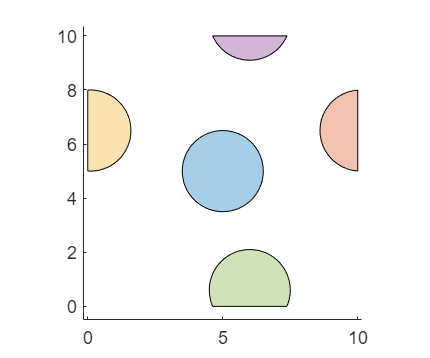

figure
plot( [psC0; psC1; psC2; psC3; psC4] ); 
axis equal

Union of fibers

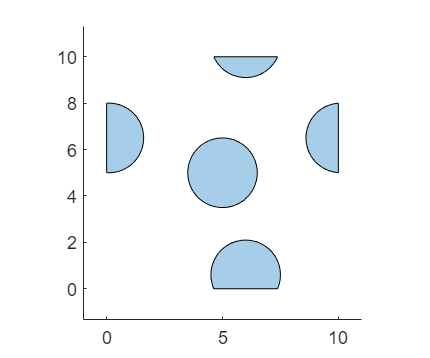

psFiber = psC0;
psFiber = union( psFiber, psC1 );
psFiber = union( psFiber, psC2 );
psFiber = union( psFiber, psC3 );
psFiber = union( psFiber, psC4 );

figure
plot( psFiber ); 
axis equal

### Cell array of polyshape

We put them into a cell array - psCell. Each element in psCell represent different parts. It's like labelling.

psCell = { psMatrix; psFiber };

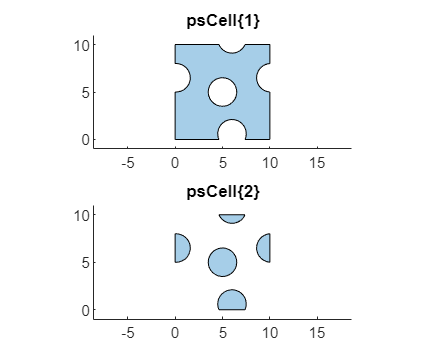

figure
for i = 1: length(psCell)
    subplot(2,1,i);
    plot( psCell{i} );  axis equal;
    title(['psCell\{' num2str(i), '\}']);
end

## Polygonal Boundaries

### Convert to polygonal boundaries

Convert the cell array of polyshape 'psCell' to a cell array of polygonal boundaries 'bounds'

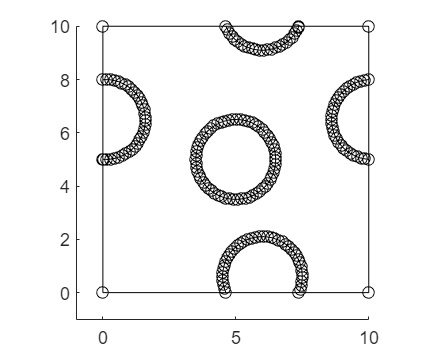

bounds = polyshape2bound(psCell);

% plot boundaries and show all vertices
plotBounds(bounds,false,'ko-')

### Add intersect points

We use function addIntersectPnts to add intersect points to 'bounds'. If we don't add intersect points, mesh generation may fail.

tol_intersect = 1e-6;   % distance tolerance for intersect
bounds = addIntersectPnts( bounds, tol_intersect );

### Simplify boundaries

We want to reduce the number of vertices on the circle.

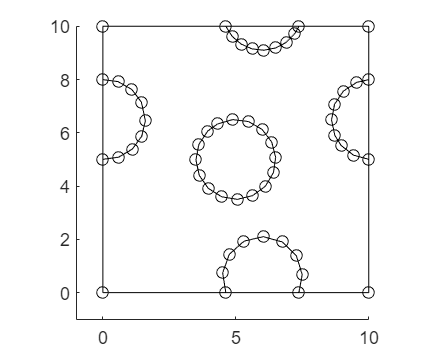

boundsCtrlP = getCtrlPnts( bounds );

% simplify polyline using Douglas-Peucker algorithm
tolerance = 0.05;
boundsReduced= simplifyBounds( boundsCtrlP, tolerance );

% show all vertices
plotBounds(boundsReduced,false,'ko-')

## Method 1 - Add uniform seeds to all boundaries

We do this via opt.bound_size

hmax = 500; 
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity
opt.bound_size = 0.5;
opt.tf_preserve = 1;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( boundsReduced, hmax, grad_limit, opt );

Plot mesh

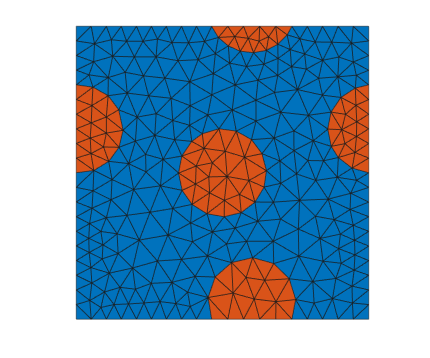

color = 1;
plotMeshes( vert,tria,tnum, color );

checkPBCNode( vert );

PBC Check Passed: All opposite boundary nodes are aligned.


Check mesh quality. 

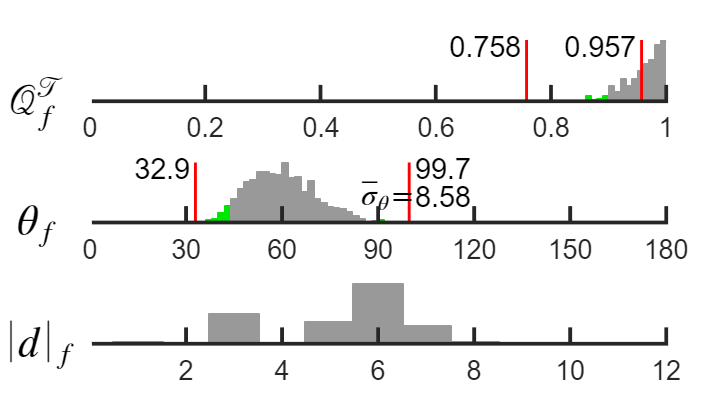

figure
tricost( vert, tria );

## Method 2 - Add uniform seeds to the outermost boundary

We do this via opt.outerbound_size

hmax = 500; 
grad_limit = 0.25;

opt = [];
opt.disp = inf;     % silence verbosity
opt.outerbound_size = 0.5;
opt.tf_preserve = 1;

[vert,tria,tnum,vert2,tria2] = bounds2mesh( boundsReduced, hmax, grad_limit, opt );

Plot mesh

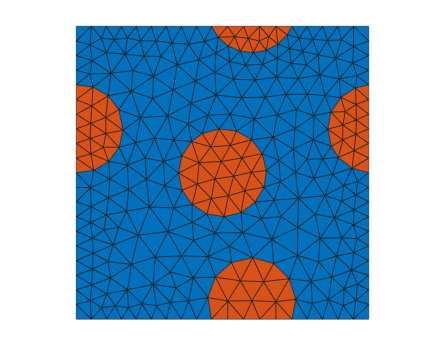

color = 1;
plotMeshes( vert,tria,tnum, color );

checkPBCNode( vert );

PBC Check Passed: All opposite boundary nodes are aligned.


Check mesh quality. 

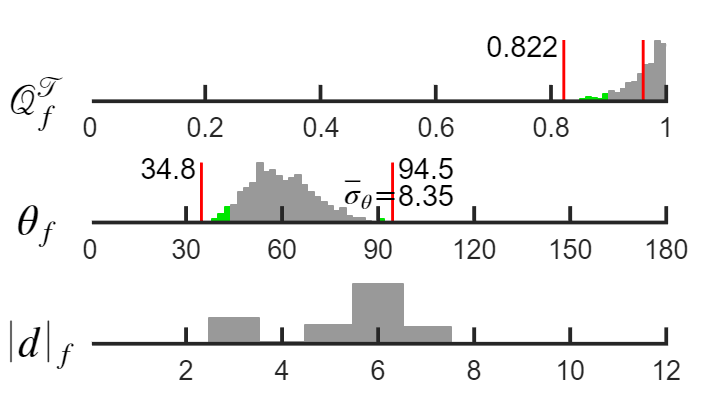

figure
tricost( vert, tria );

## A bad case

When creating geometry using polyshape objects, we need to be careful. Here, a bad case is demostrated.

clearvars

Start with a square.

vertex = 10*[ 0 0; 1 0; 1 1; 0 1 ];
psSq = polyshape(vertex);

Create a circle.

t = 0.05:0.1:2*pi;
x1 = 5 + 1.5*cos(t);
y1 = 5 + 1.5*sin(t);
psC0 = polyshape(x1,y1);

Translate

psC1 = translate( psC0, [5.1, 1.5] );
psC2 = translate( psC0, [-4.9, 1.5] );

psC3 = translate( psC0, [1, 5.6] );
psC4 = translate( psC0, [1, -4.4] );

Plot them together.

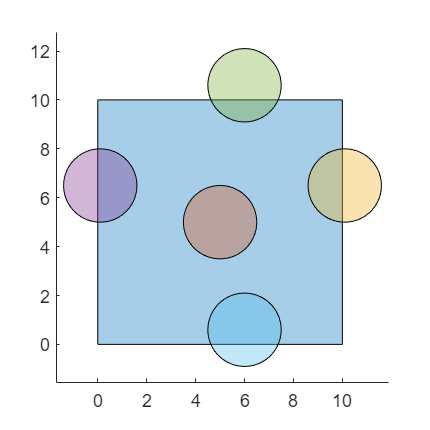

figure
plot( [psSq; psC0; psC1; psC2; psC3; psC4] ); 
axis equal

Create fiber

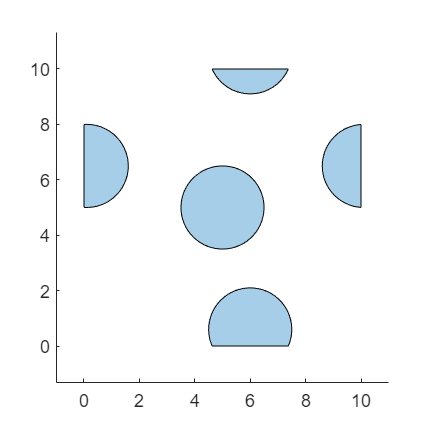

psC1 = intersect( psC1, psSq );
psC2 = intersect( psC2, psSq );
psC3 = intersect( psC3, psSq );
psC4 = intersect( psC4, psSq );

psFiber = psC0;
psFiber = union( psFiber, psC1);
psFiber = union( psFiber, psC2);
psFiber = union( psFiber, psC3);
psFiber = union( psFiber, psC4);

figure
plot( psFiber ); 
axis equal

Create matrix

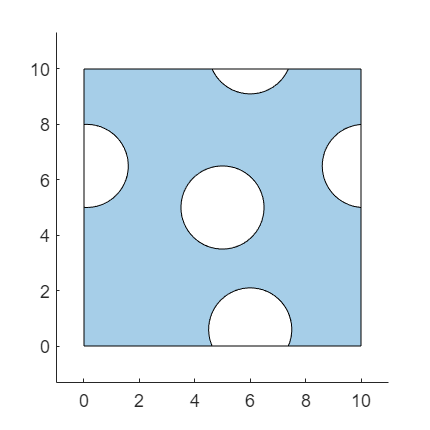

psMatrix = subtract( psSq, psFiber );

figure
plot( psMatrix ); 
axis equal

We saw that the outer edges in the matrix are wierd. Some edges are not supposed to there. If we proceed with this geometry, the 2d mesh generation would fail.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo